# Worldbank API Access

## Introduction

A simple tool to access data from worldbank open api url in MATLAB environment.

See more details about [the developer informations](https://datahelpdesk.worldbank.org/knowledgebase/topics/125589-developer-information?lang=en).

**Special notice**: Non-commerial use.

## Requirements

- support `jsondecode` built-in function

- support `matlab.net.* `package

## Method Lists

*Basic Methods*

- `isconnection`                  - check the connection

- `close`                               - delete the connection object

- `importdataset`                - import/repair the datasets automatically

- `completion`                      - a method used for tab completion

*Advanced Data API Queries Methods*

- `getSources `                    - Source Queries

- `getConcepts`                    - Concepts Queries

- `getConceptVariables`     - Concept Variables Queries

- `query`                                - Advanced Data Queries

*Aggregate API Queries Methods*

- `aggregate`                        - Aggregate API Queries

*Country API Queries Methods*

- `country`                            - Country API Queries

*Indicator API Queries Methods*

- `indicator`                        - Indicator API Queries

*API Basic Call Structures*

- `header`                              - create query structs

- `send`                                  - retrieve data

*Topic API Queries Methods*

- `topic`                                 - topic api queries

## GettingStarted

create a `wb` connection object.

conn = wb()

conn =   wb with properties:

     url: 'http://www.worldbank.org'
    root: 'D:\Program Files\MATLAB\Documents\WorldBank API Access\@wb'


generate a request struct.

request = header(conn, 'country','all',...
    'indicator','SP.POP.TOTL',...
    'date','2000');

send the request struct to get data

population_data = send(conn,request)

population_data = 2×1 cell array
    {  1×1 struct}
    {264×1 struct}


Advanced API Queries

population_data_adv = query(conn,'source','40',...
    'time','YR2000',...
    'country','all',...
    'series','SP.POP.TOTL')

population_data_adv = struct with fields:
           page: 1
          pages: 1
       per_page: 9999
          total: 259
    lastupdated: '2018-09-20'
         source: [1×1 struct]


check the connection

X = isconnection(conn)

X = logical
   1


close the connection

close(conn);

## Demo

- Display the first five GDP per capita countries.

- Comparing stock market yields among different countries.

**Display the first five GDP per capita countries.**

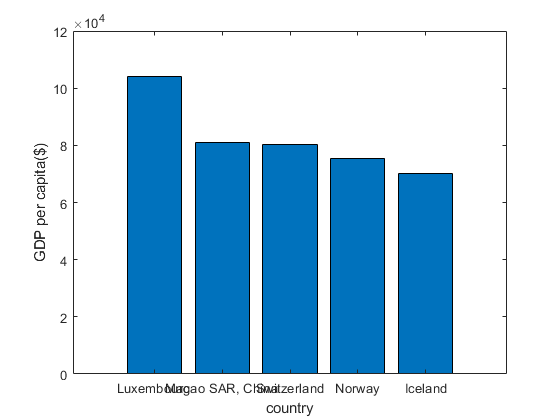

% make a connection to wb api.
conn = wb();

% fetch gdp per capita data.
gdp_data = query(conn,'source','2',...
    'series','NY.GDP.PCAP.KN',...
    'country','CHL',...
    'time','all');

% parse the data
raw_data = {gdp_data.source.data.value};

% let loss data be NaNs
for n = 1:length(raw_data)
    if isempty(raw_data{n})
        raw_data{n} = NaN;
    end
end

% rank data
raw_data = [raw_data{:}];
[top5,ranks] = maxk(raw_data,5);

% get the country labels
country = cell(1,5);
for n = 1:5
    country{n} = ...
        gdp_data.source.data(ranks(n)).variable(1).value;
end

% make a bar chart
bar(top5);
set(gca,'xticklabel',country);
xlabel('country');
ylabel('GDP per capita($)');

% close the connection
close(c);

**Comparing stock market yields among different countries.**

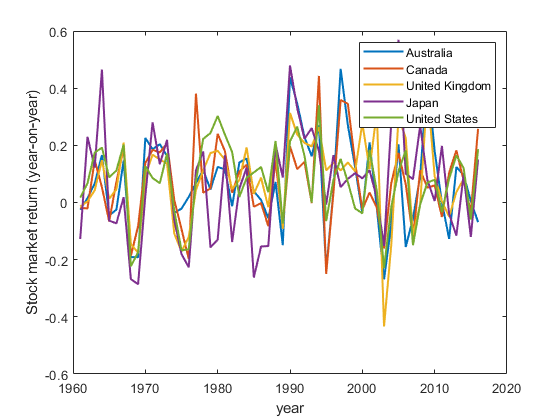

obj = wb();

% import the source table to recognize which source do "stock market
% yields" belong to.
[~,tbl] = completion(obj,'getSources');

% the 'Global Financial Development' source code is '32'
% import the concept table of source code '32'
[~,tbl_concept] = completion(obj,'getConcepts','32');

% get the concept variables of 'series' concept within '32'
[~,tbl_variables] = completion(obj,'getConceptVariables','32','series');

% we find the target indicator 'Stock market return (%, year-on-year)',
% whose id is 'GFDD.OM.02'.

% specify time range
% pass

% specify country set: high-income income country
% use 'aggregate' method
tbl_incomelevel = aggregate(obj,'incomelevel');

% we know that high-income code is 'hic'
country_high = obj.country('all','incomelevel','hic');
country_high = {country_high{2}.id}; % get the list of high-income

% query step
response = query(obj,'source','32',...
    'Series','GFDD.OM.02',...
    'Time','all',...
    'Country',country_high);

% number of country
for i = 1:length(response.source.data)
    c{i} = response.source.data(i).variable(1).value;
end
num = length(unique(c)); % num = 78

% parse data
str = unique(c,'stable');
data = {response.source.data.value};
data = reshape(data,length(data)/num, num);

x = data(:,[6,14,29,42,77]);
for i = 1:size(x,1)
    for j = 1:size(x,2)
        if isempty(x{i,j})
            x{i,j} = NaN;
        end
    end
end
legend_string = str([6,14,29,42,77]);

% plot data
plot(1960:2017,cell2mat(x)/100,'linewidth',1.5);
legend(legend_string);
xlabel('year');
ylabel('Stock market return (year-on-year)');

close(obj)

## External Readings

- [**API documentation of WorldBank**](https://datahelpdesk.worldbank.org/knowledgebase/topics/125589-developer-information?lang=en)

- [**The idea from datafeed toolbox**](https://www.mathworks.com/help/datafeed/index.html?searchHighlight=datafeed&s_tid=doc_srchtitle)

- [**Learn something about HTTP interface technique**](https://www.mathworks.com/help/matlab/http-interface.html?s_tid=srchtitle&requestedDomain=)

- [**Try to make your own function signatures**](https://www.mathworks.com/help/matlab/matlab_prog/customize-code-suggestions-and-completions.html?lang=en)

- [**How to manage your project by class folder**](https://www.mathworks.com/help/matlab/matlab_oop/organizing-classes-in-folders.html?s_tid=doc_ta)